# **Section 1: Image Restoration on Blurred License Plate (without noise)**

In this section we are going to simluate on how to restore a degraded image caused by motion blur.

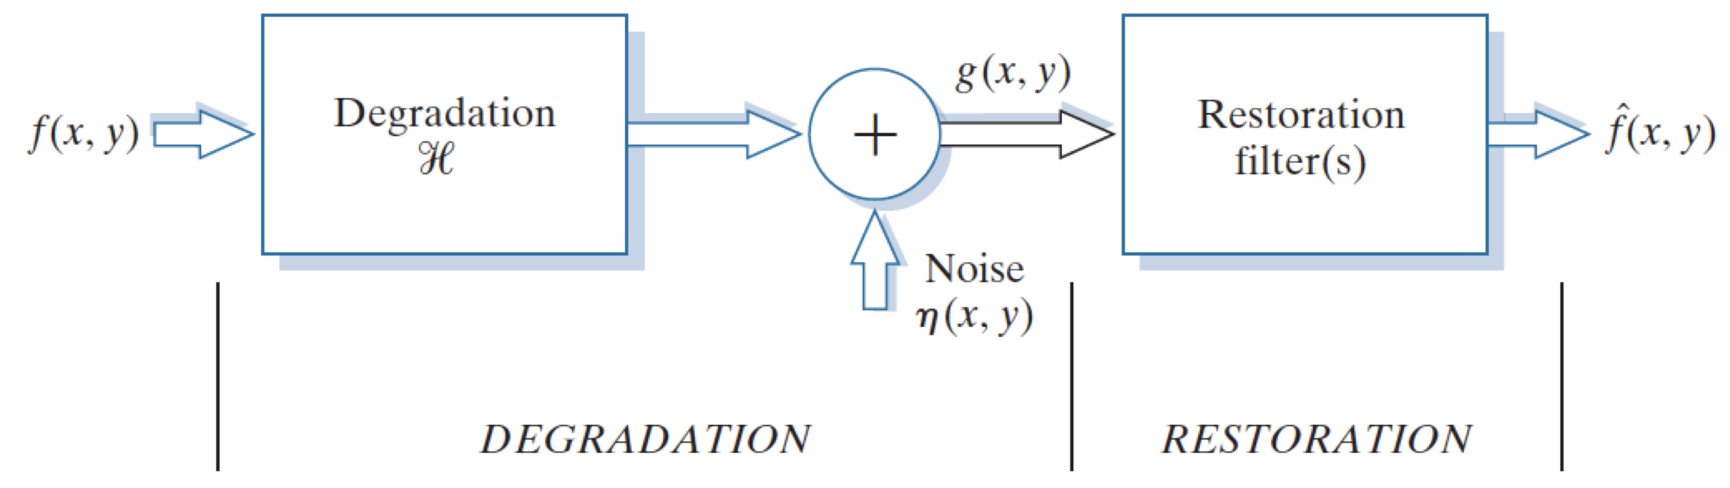

## Step - 1 Simulating Blurred Image

The blurred image is simulated using a Motion Filter

Read and displaying the original image before degradation process.

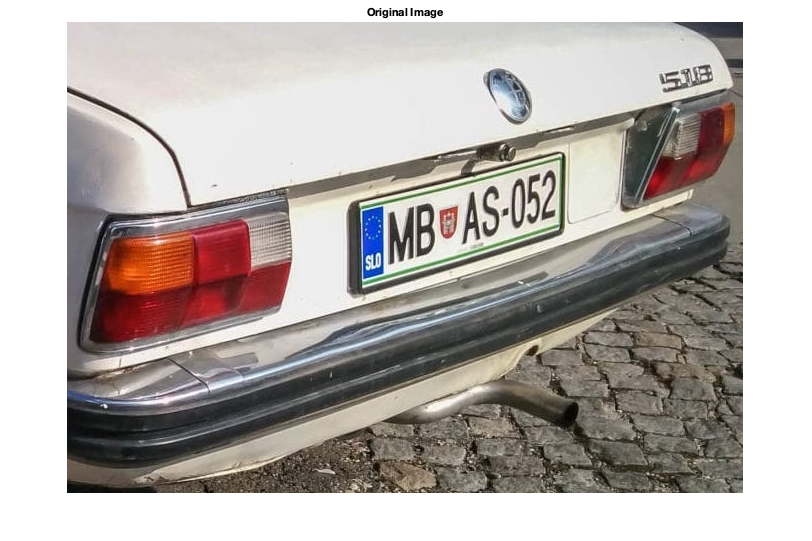

original_image = imread('data/cars_two_a.jpeg');
imshow(original_image);
title('Original Image');

Degrading the original image using the Degrade function with motion blurr.

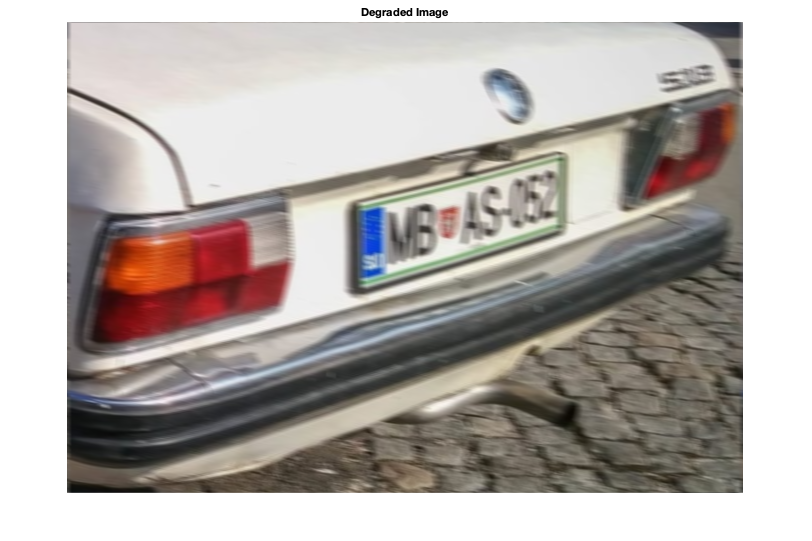

len = 10;     % length of linear motion
theta = -10;     % angle of motion in degrees in a counter-clockwise direction

degraded_image = Degrade(original_image,len,theta);

imshow(degraded_image);
title('Degraded Image');

Saving the degraded image into a file.

imwrite(degraded_image,'data/cars_two_a_len=50_theta=-15.jpg')

## Step 2 - Restoring The Image

Now we restore the degraded image using the Inverse Filter. The results of Wiener Filter and Inverse Filter, in this case is the same, because we do not introduce noise onto the image.

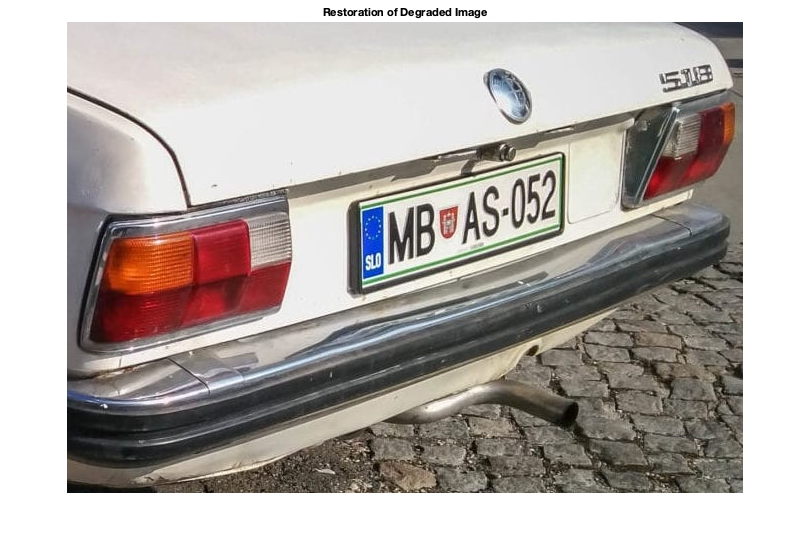

len = 10;
theta = -10;
restored_image_Inverse = Inverse(degraded_image,len,theta);

imshow(restored_image_Inverse)
title('Restoration of Degraded Image');

Saving the restored image into a file.

imwrite(restored_image_Inverse,'data/cars_two_a_Inverse_len=50_theta=-15.jpg')

In this part we restore the degraded image using Wiener Filter.

len = 50;
theta = -15;
SNR = 0;    % since there is no noise
restored_image_Wiener = Wiener_Filter(degraded_image,len,theta,SNR);
imshow(restored_image_Wiener)
title('Restoration of Degraded Image');

Saving the restored image into a file.

imwrite(restored_image_Wiener,'data/cars_two_a_Wiener_len=50_theta=-15.jpg')